# Sample 4-6

## 線形シフト不変システム

循環畳み込み行列

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Linear shift-invariant systems

Circular convolution matrix

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### 単変量循環畳み込み

(Univariate circular convolution)

有限インパルス応答(FIR)$\{h[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{h}}\subset\mathbb{Z}}$を有する線形シフト不変システム $T(\cdot)$を仮定する． (Let us assume a linear shift-invariant system $T(\cdot)$ with a finite impulse response (FIR) $\{h[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{h}}\subset\mathbb{Z}}$.)

配列 $\{u[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{u}}\subset\mathbb{Z}}$に対する周期拡張後の$T(\cdot)$ の応答 $\{v[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{v}}\subset\mathbb{Z}}$は周期 $Q\in\mathbb{N}$ を法とする単変量循環畳み込み (The response $\{v[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{v}}\subset\mathbb{Z}}$ of  $T(\cdot)$  to a sequence $\{u[n]\in\mathbb{R}\}_{n\in{\Omega_\mathrm{u}}\subset\mathbb{Z}}$ after periodic extension can be represented by univariate circular convolution with period $Q$ as ) 

        
$$\{v[n]\}_n =T\left(\{u[n]\}_n\right) = \sum_{k\in\Omega_\mathrm{h
}}h[k]\{u\left[(\!(n-k)\!)_Q\right]\}_n.$$


により表現できる．ただし，(where) 

        
$$(\!(n)\!)_Q = n - Q\left\lfloor Q^{-1}n\right\rfloor.$$


は， ${Q}$を法とする ${n}$ の剰余である．( denotes the ${n}$ modulo ${Q}$.) 

#### 信号の生成

(Signal generation)

% Generating an input sequence u[n] of finite support region
Q = 6; 
ugen = "(1:Q)";
u = eval(ugen)

u =      1     2     3     4     5     6


#### インパルス応答の設定

(Setting the impulse response)

% Setting the shift amount 
h = [1 0 -1];

#### 写像の定義

(Definition of a map)

% Definition of map T as a modulo-Q circular convolution with h[n]
mapT = @(x) cconv(x,h,Q);

#### 写像の結果

(Result of mapping)

% Mapping with the circular convolution T(.)
v = mapT(u)

v =     -4    -4     2     2     2     2


### 単変量循環畳み込みの行列表現

(Matrix representation of the univariate circular convolution)

単変量循環畳み込み演算も (The univariate circular convolution can also be represented as a matrix as)

        
$$\mathbf{v}=\mathbf{Tu},$$


のように行列表現できる． 

インパルス応答 $\{h[n]\}_n$ のサポート領域 $\Omega_\mathrm{h}=\{0,1,2\}$が，入力信号$\{u[n]\}_n$のサポート領域$\Omega_\mathrm{u}=\{0,1,2,3,4,5\}$ よりも短く周期 $Q=|\Omega_\mathrm{u}|$ と設定されているとき，出力信号$\{v[n]\}_n$のサポート領域も$\Omega_\mathrm{v}=\Omega_\mathrm{u}$となり，(If the support region $\Omega_\mathrm{h}=\{0,1,2\}$ of the impulse response $\{h[n]\}_n$ is shorter than the support region $\Omega_\mathrm{u}=\{0,1,2,3,4,5\}$ of the input signal $\{u[n]\}_n$ and  the period is set as $Q=|\Omega_\mathrm{u}|$, then the support region of the output signal $\{v[n]\}_n$ becomes also $\Omega_\mathrm{v}=\Omega_\mathrm{u}$, and we have )

       
$$\mathbf{v}=\mathrm{vec}\left(\{v[{n}]\}_{n}\right)=\left(\begin{array}{c}v[0]\\v[1]\\v[2]\\v[3]\\v[4]\\v[5]\end{array}\right), \mathbf{u}=\mathrm{vec}\left(\{u[{n}]\}_{n}\right)=\left(\begin{array}{c}u[0]\\u[1]\\u[2]\\u[3]\\u[4]\\u[5]\end{array}\right)$$


        
$$\mathbf{T}
=\left(\begin{array}{cccccc}
h[0] & 0  & 0 & 0 & h[2] & h[1] \\
h[1] & h[0]  & 0 & 0 & 0 & h[2] \\
h[2] & h[1]  & h[0] & 0 & 0 & 0 \\
0 & h[2] & h[1]  & h[0] & 0 & 0 \\
0 & 0 & h[2] & h[1]  & h[0] & 0 \\
0 & 0 & 0 & h[2] & h[1]  & h[0]  
\end{array}\right).$$


と表現できる．

#### 単変量循環畳み込みの行列生成

(Matrix generation of univariate circular convolution)

% Find the matrix representation of the univariate circular convolution
T = zeros(length(u));
for idx = 1:length(u)
    % Generating a standard basis vector
    e = zeros(size(u),'like',u);
    e(idx) = 1;
    % Response to the standard basis vector
    T(:,idx) = mapT(e); 
end
% Matrix representation of the univariate circular convolution
T

T =     1.0000         0   -0.0000         0   -1.0000         0
         0    1.0000         0   -0.0000         0   -1.0000
   -1.0000         0    1.0000         0         0         0
         0   -1.0000         0    1.0000         0   -0.0000
   -0.0000         0   -1.0000         0    1.0000         0
         0         0         0   -1.0000         0    1.0000


### 行列演算による単変量循環畳み込み

(Univariate circular convolution by matrix operation)

循環畳み込みも可換図に沿って (Circular convolution can also be computed as)

    
$$\{v[{n}]\}_{n}=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{v}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{Tu}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}\left(\{u[n]\}_n\right)$$


のように行列演算が可能である．すなわち，(along the commutative diagram. That is, we have)

        
$$T=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}.$$


と表現できる．

% Column vectorization of sequence u[n]
vecu = u(:);

% Matrix operation
vecv = T*vecu;

% Reshaping the result into the row sequnece
recv = reshape(vecv,[1 Q])

recv =    -4.0000   -4.0000    2.0000    2.0000    2.0000    2.0000


#### 行列演算による単変量循環畳み込みの評価

(Evaluation of univariate circular convolution by matrix operation)

% Comparizon between mapping and matrix operation
mymse = @(x,y) mean((double(x)-double(y)).^2,'all');
mymse(v,recv)

ans = 3.6156e-31

### 2変量循環畳み込み

(Bivariate circular convolution)

有限インパルス応答(FIR)インパルス応答 $\{h[\mathbf{n}]\}_\mathbf{n}$ を有する線形シフト不変システム $T(\cdot)$を仮定する．(Assume a linear shift-invariant system T with a bivariate finite impulse response (FIR) $\{h[\mathbf{n}]\in\mathbb{R}\}_{\mathbf{n}\in{\Omega_\mathrm{h}}\subset\mathbb{Z}^2}$.)  

 配列$\{u[\mathbf{n}]\}_\mathbf{n}$に対する周期拡張後の$T(\cdot)$ の応答$\{v[\mathbf{n}]\}_\mathbf{n}$は周期 $\mathbf{Q}\in\mathbb{Z}^{2\times 2} $($\det\mathbf{Q}\neq 0$) を法とする2変量循環畳み込み

        
$$\{v[\mathbf{n}]\}_\mathbf{n} =T\left(\{u[\mathbf{n}]\}_\mathbf{n}\right) = \sum_{\mathbf{k}\in\Omega_\mathrm{h}}h[\mathbf{k}]\{u\left[(\!(\mathbf{n}-\mathbf{k})\!)_\mathbf{Q}\right]\}_\mathbf{n},$$


により表現できる．(The response $\{v[\mathbf{n}]\}_\mathbf{n}$ of $T(\cdot)$ after periodic extension to array $\{u[\mathbf{n}]\}_\mathbf{n}$ can be represented by bivariate circular convolution with period $\mathbf{Q}$,) ただし，$\mathbf{Q}\in\mathbb{Z}^{2\times2}(\det\mathbf{Q}\neq 0)$は周期行列,  $\{v[\mathbf{n}]\in\mathbb{K}\}_{\mathbf{n}\in\Omega\subset\mathbb{Z}^2}$は出力配列，(where  $\mathbf{Q}\in\mathbb{Z}^{2\times2}(\det\mathbf{Q}\neq 0)$ is the period matrix,  $\{v[\mathbf{n}]\in\mathbb{K}\}_{\mathbf{n}\in\Omega\subset\mathbb{Z}^2}$ is the destination array and)

        
$$(\!(\mathbf{n})\!)_\mathbf{Q} = \mathbf{n} - \mathbf{Q}\left\lfloor \mathbf{Q}^{-1}\mathbf{n}\right\rfloor$$


は， $\mathbf{Q}$を法とする $\mathbf{n}$ の剰余である．( denotes the $\mathbf{n}$ modulo $\mathbf{Q}$.) 

#### 信号の生成

(Signal generation)

% Generating an input array u[n1,n2] of finite support region
N1 = 2; % # of rows
N2 = 3; % # of columns
ugen = "reshape((0:N1*N2-1),[N1 N2])";
u = eval(ugen)

u =      0     2     4
     1     3     5


#### インパルス応答の設定

(Setting the impulse response)

h = [1 -1 ; 1 -1]

h =      1    -1
     1    -1


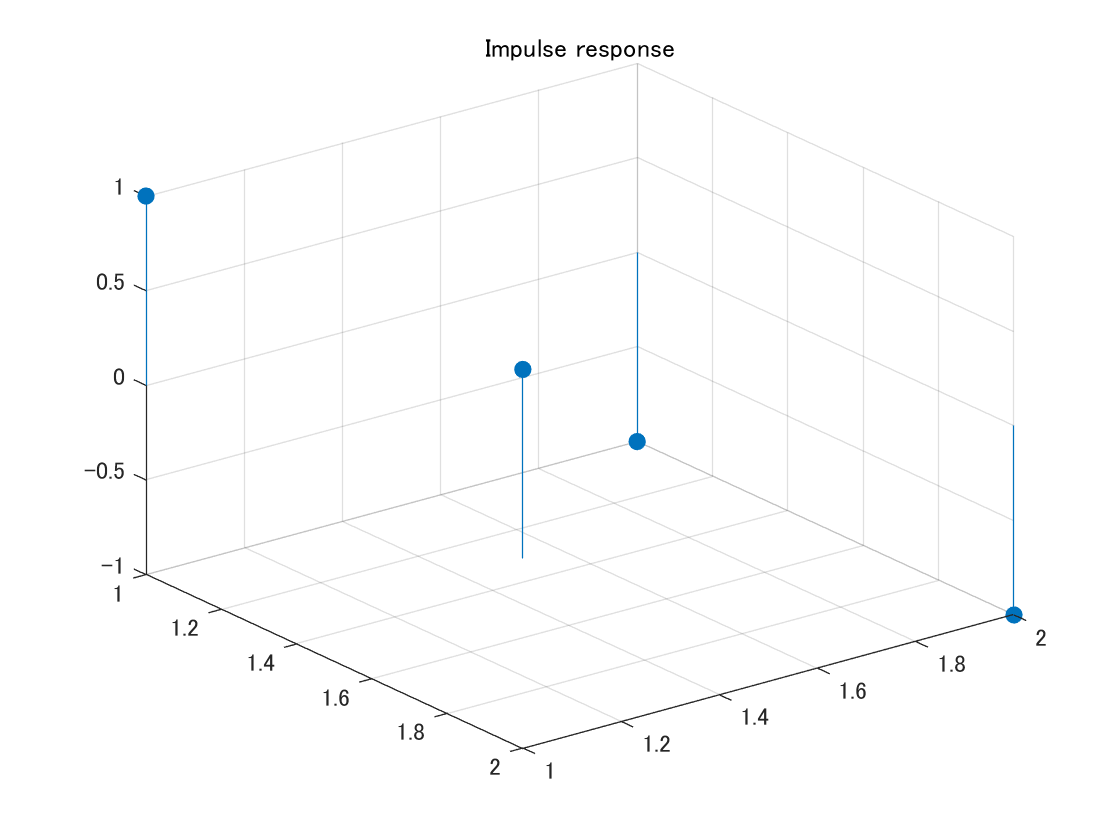

figure(1)
stem3(h,'filled')
axis ij
title('Impulse response')

#### 写像の定義

(Definition of a map)

% Definition of map T as a circular convolution with h[n]
mapT = @(x) imfilter(x,h,'conv','circ');

#### 写像の結果

(Result of mapping)

% Mapping with the circular shift T(.)
v = mapT(u)

v =      4     4    -8
     4     4    -8


### 2変量循環畳み込みの行列表現

(Matrix representation of the bivariate circular convolution)

2変量循環畳み込み演算も (The bivariate circular convolution can also be represented as a matrix as)

        
$$\mathbf{v}=\mathbf{Tu},$$


のように行列表現できる． 

インパルス応答 $\{h[\mathbf{n}]\}_\mathbf{n}$ のサポート領域 $\Omega_\mathrm{h}=\{0,1\}\times \{0,1\}$が，入力信号$\{u[\mathbf{n}]\}_\mathbf{n}$のサポート領域$\Omega_\mathrm{u}=\{0,1\}\times \{0,1,2\}$ よりも狭く周期行列が $\mathbf{Q}=\left(\begin{array}{cc}N_1 & 0 \\ 0 & N_2\end{array}\right)=\left(\begin{array}{cc}2 & 0 \\ 0 & 3\end{array}\right)$ と設定されているとき，出力信号$\{v[\mathbf{n}]\}_\mathbf{n}$のサポート領域も$\Omega_\mathrm{v}=\Omega_\mathrm{u}$となり，(If the support region $\Omega_\mathrm{h}=\{0,1\}\times \{0,1\}$ of the impulse response $\{h[\mathbf{n}]\}_\mathbf{n}$ is narrower than the support region $\Omega_\mathrm{u}=\{0,1\}\times \{0,1,2\}$ of the input signal $\{u[\mathbf{n}]\}_\mathbf{n}$ and  the period is set as $\mathbf{Q}=\left(\begin{array}{cc}N_1 & 0 \\ 0 & N_2\end{array}\right)=\left(\begin{array}{cc}2 & 0 \\ 0 & 3\end{array}\right)$, then the support region of the output signal $\{v[\mathbf{n}]\}_\mathbf{n}$ becomes also $\Omega_\mathrm{v}=\Omega_\mathrm{u}$, and we have )

          
$$\mathbf{v}=\mathrm{vec}\left(\{v[\mathbf{n}]\}_\mathbf{n}\right)=\left(\begin{array}{c}
v[0,0]\\v[1,0]\\v[0,1]\\v[1,1]\\\vdots\\v[1,2]\end{array}\right), \mathbf{u}=\mathrm{vec}\left(\{u[\mathbf{n}]\}_\mathbf{n}\right)=\left(\begin{array}{c}u[0,0]\\u[1,0]\\u[0,1]\\u[1,1]\\\vdots\\u[1,2]\end{array}\right)$$


        
$$\mathbf{T}
=\left(\begin{array}{cccccc}
h[1,1] & h[0,1]  & h[1,0] & h[0,0] & 0 & 0 \\
h[0,1] & h[1,1]  & h[0,0] & h[1,0] & 0 & 0 \\
0 & 0 &h[1,1] & h[0,1]  & h[1,0] & h[0,0]  \\
0 & 0 &h[0,1] & h[1,1]  & h[0,0] & h[1,0]  \\
h[1,0] & h[0,0] & 0 & 0 &h[1,1] & h[0,1]  \\
h[0,0] & h[1,0] & 0 & 0 &h[0,1] & h[1,1]  
\end{array}\right).$$


と表現できる．

#### 2変量循環畳み込みの行列生成

(Bivariate circular convolution matrix generation)

% Find the matrix representation of the circular convolution
T = zeros(numel(u));
for idx = 1:numel(u)
    % Generating a standard basis vector
    e = zeros(size(u),'like',u);
    e(idx) = 1;
    % Response to the standard basis vector
    T(:,idx) = reshape(mapT(e),[size(T,1) 1]); 
end
% Matrix representation of the convolution
T

T =     -1    -1     1     1     0     0
    -1    -1     1     1     0     0
     0     0    -1    -1     1     1
     0     0    -1    -1     1     1
     1     1     0     0    -1    -1
     1     1     0     0    -1    -1


### 行列演算による2変量循環畳み込み

(Bivariate circular convolution by matrix operation)

2変量循環畳み込みも可換図に沿って (Bivariate circular convolution can also be computed as)

    
$$\{v[\mathbf{n}]\}_\mathbf{n}=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{v}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\left(\mathbf{Tu}\right)=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}\left(\{u[\mathbf{n}]\}_\mathbf{n}\right)$$


のように行列演算が可能である．すなわち，(along the commutative diagram. That is, we have)

        
$$T=\mathrm{vec}_{\Omega_\mathrm{v}}^{-1}\circ\mathbf{T}\mathrm{vec}_{\Omega_\mathrm{u}}.$$


と表現できる．

% Column vectorization of sequence u[n]
vecu = u(:);

% Matrix operation
vecv = T*vecu;

% Reshaping the result into the row sequnece
recv = reshape(vecv,[N1 N2])

recv =      4     4    -8
     4     4    -8


#### 行列演算による2変量循環畳み込みの評価

(Evaluation of bivariate circular convolution by matrix operation)

% Comparizon between mapping and matrix operation
mymse(v,recv)

ans = 0

© Copyright, Shogo MURAMATSU, All rights reserved.